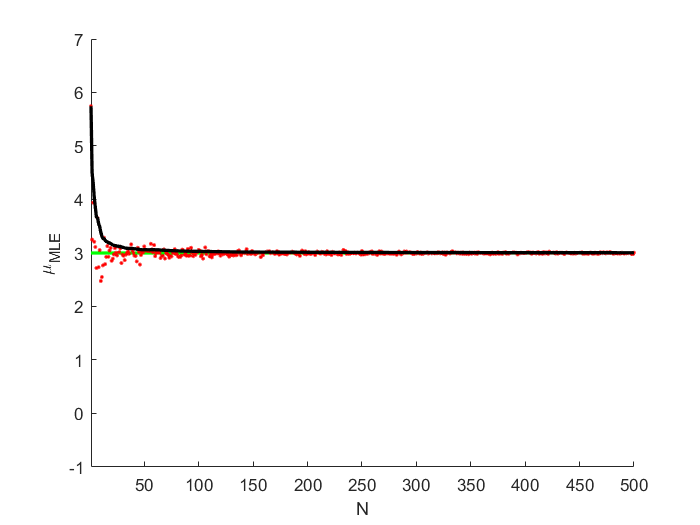

clear;clc;

mu_star = 3;
sd_star = 4;
var_star = sd_star^2;
N_max = 500;

figure(1);
axis([1 N_max mu_star-sd_star mu_star+sd_star]);
line([1 N_max],[mu_star mu_star], 'Color', 'green', 'LineWidth', 2);
xlabel('N');
ylabel('\mu_{MLE}')
hold on;
figure(2);
axis([1 N_max var_star*0.5 var_star*1.5]);
line([1 N_max],[var_star var_star], 'Color', 'green', 'LineWidth', 2);
xlabel('N');
ylabel('\sigma^{2}_{MLE}')
hold on;

exp_mu_mle_arr = [];
exp_var_mle_arr = [];
for N = 1:N_max
    exp_mu_mle = 0;
    exp_var_mle = 0;
    for n = 1:N
        y = mu_star + sd_star*randn(1,N);
        mu_mle = sum(y)/N;
        var_mle = sum((y-mu_mle).^2)/N;
        exp_mu_mle = exp_mu_mle + mu_mle;
        exp_var_mle = exp_var_mle + var_mle;
    end
    exp_mu_mle = exp_mu_mle/N;
    exp_var_mle = exp_var_mle/N;
    exp_mu_mle_arr = [exp_mu_mle_arr exp_mu_mle];
    exp_var_mle_arr = [exp_var_mle_arr exp_var_mle];

    figure(1);
    plot(N,exp_mu_mle,'.',Color='red');
    drawnow;
    figure(2);
    plot(N,exp_var_mle,'.',Color='blue');    
    drawnow;
end

figure(1);
plot(1:N,cumsum(exp_mu_mle_arr)./(1:N),'-','Color', 'black', 'LineWidth', 2);

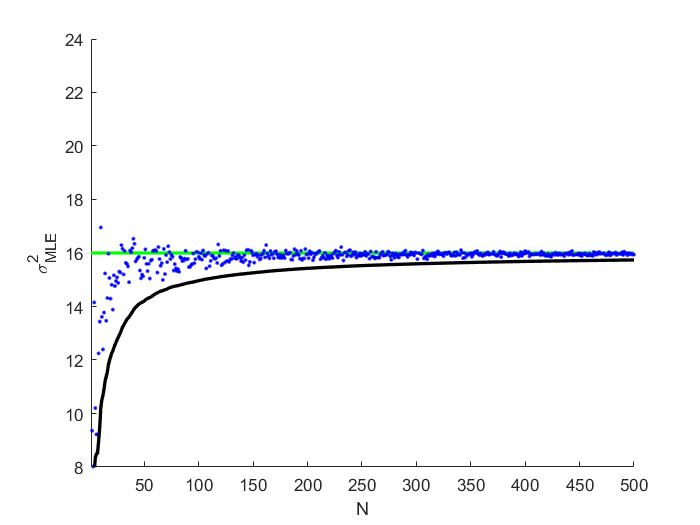

figure(2);
plot(1:N,cumsum(exp_var_mle_arr)./(1:N),'-','Color', 'black', 'LineWidth', 2);